clear
r = sym('r','real');
theta = sym('theta','real');
t = sym('t','real');

m = 1;
n = 1;
c = 100;
radius = 1;
J(r) = besselj(1, r)

$$J(r) = J_{1}\left(r\right)$$

lambda = fzero(matlabFunction(J),3) / radius

lambda = 3.8317

u(r,theta,t) = (cos(c*lambda * t) + sin(c*lambda * t)) * J(lambda*r) * (cos(m*theta) + sin(m*theta))

$$u(r, theta, t) = \left(\cos\left(\theta \right)+\sin\left(\theta \right)\right)\,\left(\cos\left(\frac{3370404214769503\,t}{8796093022208}\right)+\sin\left(\frac{3370404214769503\,t}{8796093022208}\right)\right)\,J_{1}\left(\frac{1078529348726241\,r}{281474976710656}\right)$$

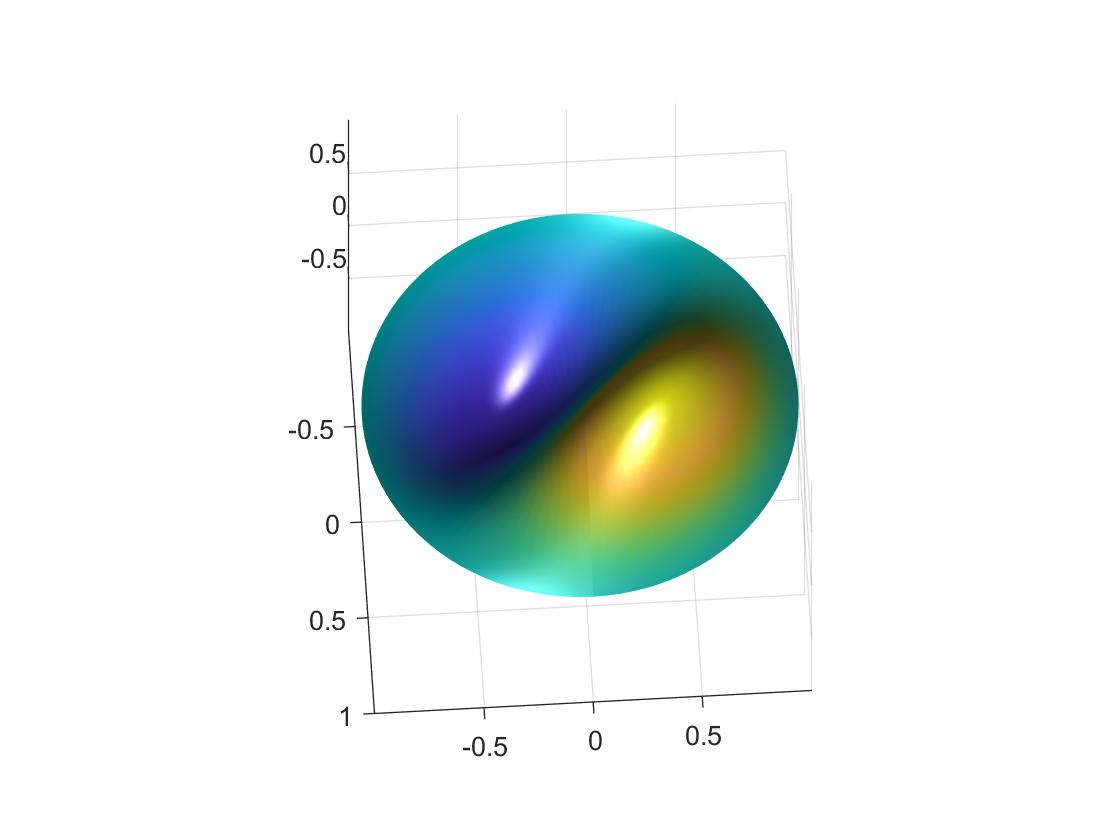

f = matlabFunction(u,'Vars',[r,theta,t]);
T = linspace(0,2*pi, 100);
R = linspace(0,radius,100);
[R,T] = meshgrid(R,T);
U = zeros(size(R));

for ii = 1:numel(R)
    U(ii) = f(R(ii), T(ii),1);
end
X = R.*cos(T);
Y = R.*sin(T);
figure
surf(X,Y,U,'LineStyle','none')
axis vis3d
lighting gouraud
light


fid = fopen("disk_eigen.csv",'w+');
fprintf(fid, "x\ty\tz\n");
fprintf(fid,"%12.8f \t %12.8f \t %12.8f \n",[X(:) Y(:) U(:)]');
fclose(fid);
